# Normalized sinc calculation

The normalized $sinc$ function is defined for $x \neq 0$ by


$$sinc(x) = \frac{sin(\pi x)}{\pi x}$$


and for $x = 0$ is defined to be the limiting value


$$sinc(0) := \lim_{x \to 0} \frac{sin(ax)}{ax} = 1$$


for all real $a \neq 0$.

It can also be defined as


$$\frac{sin(\pi x)}{\pi x} = \prod_{n=1}^\infty \bigg ( 1 - \frac{x^2}{n^2} \bigg )$$


## Ways of calculating $sinc$ in MATLAB

### 1. Using the MATLAB function for it.

By using the $sinc$ function in MATLAB, it defaults to the normalized version rather than the unnormalized one

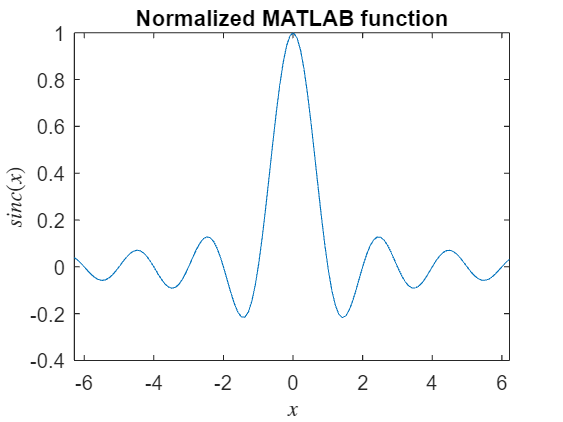

x = -2*pi:0.1:2*pi;
plot(x, sinc(x))
title('Normalized MATLAB function')
xlabel('$x$', 'Interpreter','latex')
ylabel('$sinc(x)$','Interpreter','latex')

### 2. Using `for` loops with the $sinc$ definition

By using the `x` vector we had declared, we can calculate $sinc$ using it's definition, using a `for` loop to calculate every single value, being very careful that$x = 0 \Leftrightarrow sinc(x) = 1$

n = size(x);
y = zeros(n);
    
for i = 1:n(1)
        
    for j = 1:n(2)
        if x(i, j) == 0
            y(i, j) = 1;
        else
            y(i, j) = sin(pi*x(i, j))/(pi*x(i, j));
        end
    end

end
y

y =     0.0394    0.0280    0.0135   -0.0028   -0.0194   -0.0347   -0.0470   -0.0551   -0.0580   -0.0552   -0.0468   -0.0334   -0.0162    0.0034    0.0234    0.0419    0.0570    0.0671    0.0709    0.0678    0.0577    0.0414    0.0201   -0.0042   -0.0294   -0.0530   -0.0725   -0.0858   -0.0913   -0.0878   -0.0753   -0.0544   -0.0267    0.0056    0.0396    0.0720    0.0995    0.1190    0.1280    0.1247    0.1083    0.0794    0.0395   -0.0085   -0.0606   -0.1124   -0.1587   -0.1942   -0.2143   -0.2148


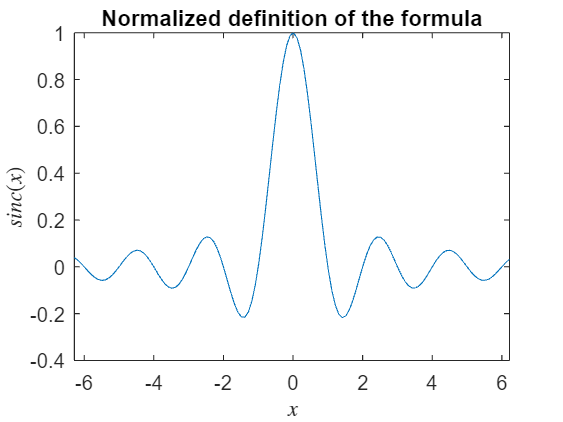

plot(x, y)
title('Normalized definition of the formula')
xlabel('$x$', 'Interpreter','latex')
ylabel('$sinc(x)$','Interpreter','latex')